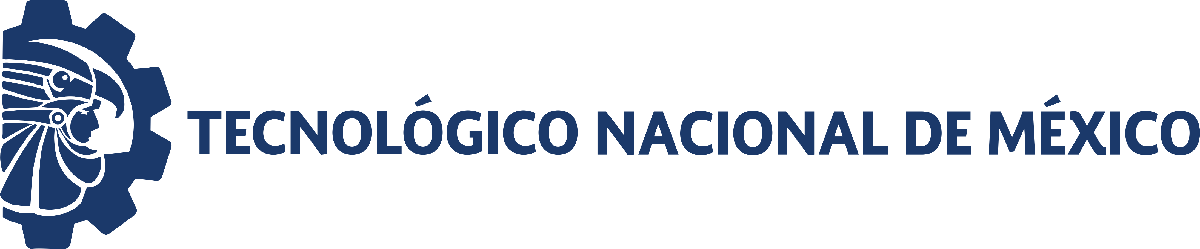                                 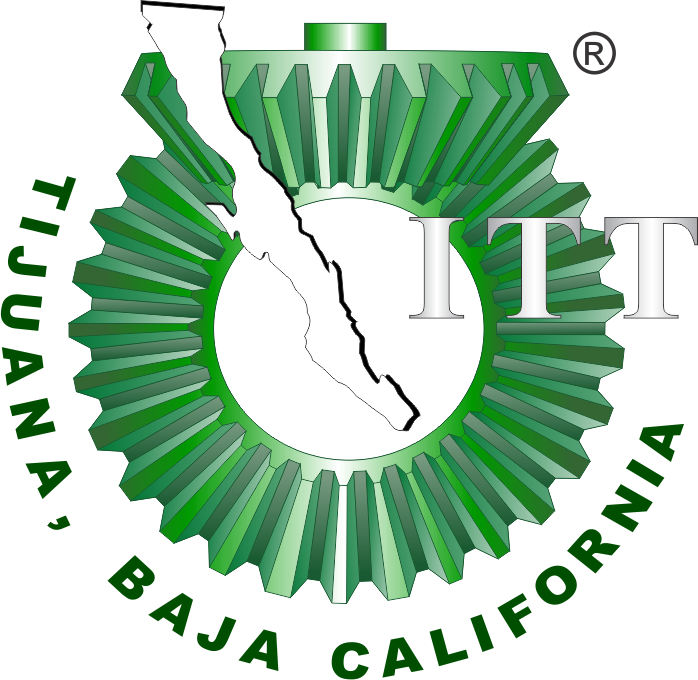

# Práctica 5: Análisis de Sistemas Biológicos

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

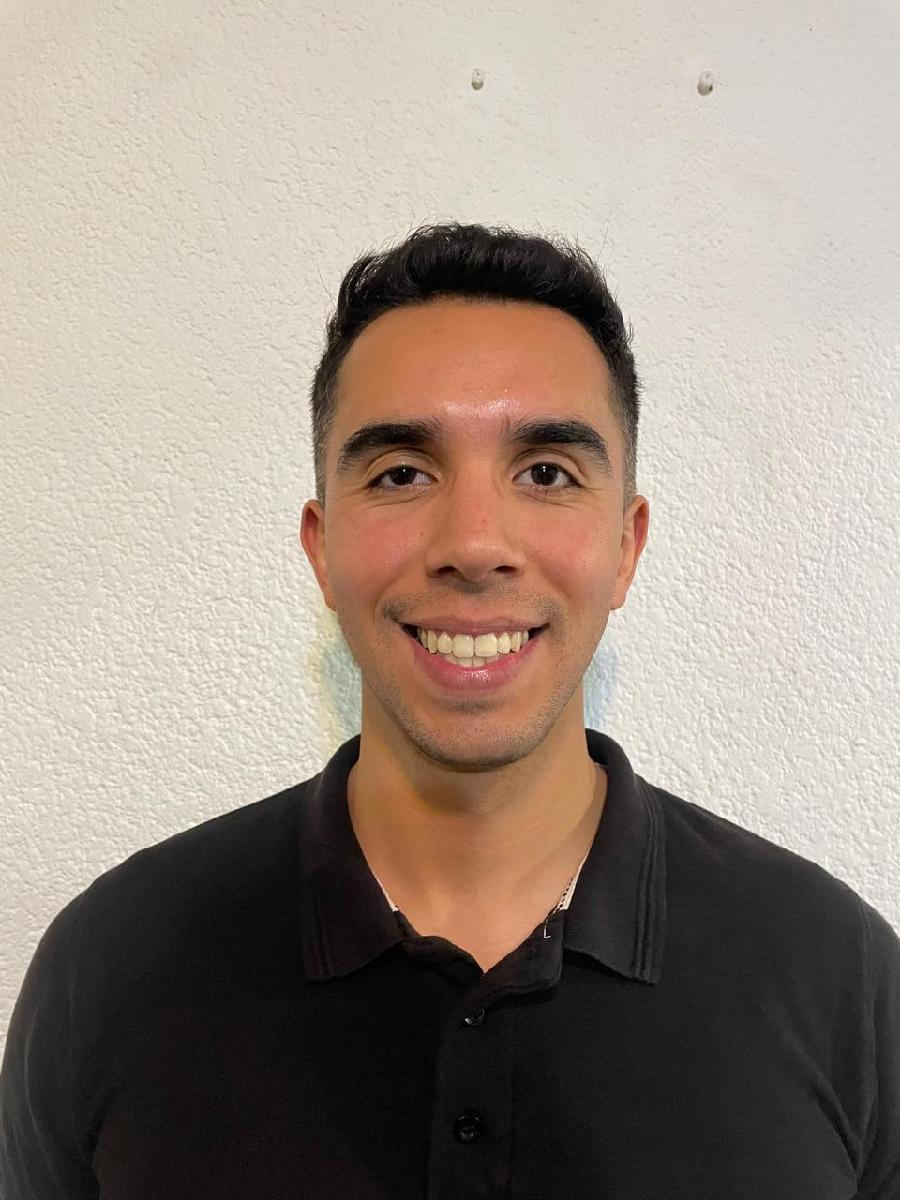

Nombre del alumno: **Carlos Andrés Gil Gárate**

Número de control: **21212743**

Correo institucional: **21212743@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## 1. Objective 

Analizar la dinámica de un sistema biológico tricompartimental modelado por ecuaciones diferenciales de primer orden, que representa la interacción entre células patológicas, células sanas y células efectoras del sistema inmunológico. Se busca evaluar el comportamiento del sistema ante diferentes valores del parámetro de bifurcación $a_{12}$, observando transiciones entre dinámicas caóticas, órbitas periódicas, ciclos límite y puntos de equilibrio.

## 2. Normalized Mathematical Models 

#### 2.1 Chaotic Atractor 

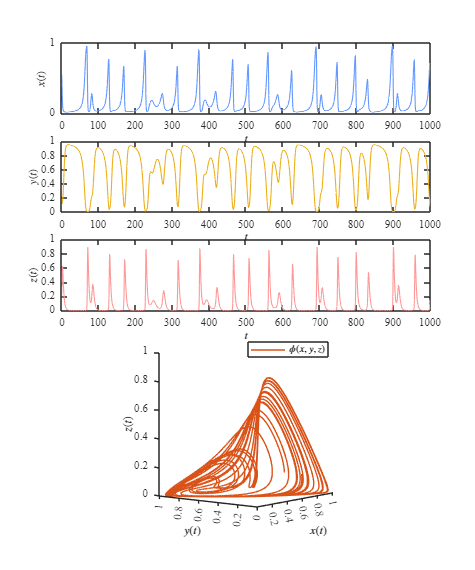

clc; clear; close all; warning('off','all')
P = [1,1,2.5,0.6,1,1.5,3,0.3,0.4];
[t,x,y,z] = system(0.555,0.148,0.172,P,1,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'Atractor Caótico.pdf','ContentType','vector')

### 2.2 Periodic Orbit  

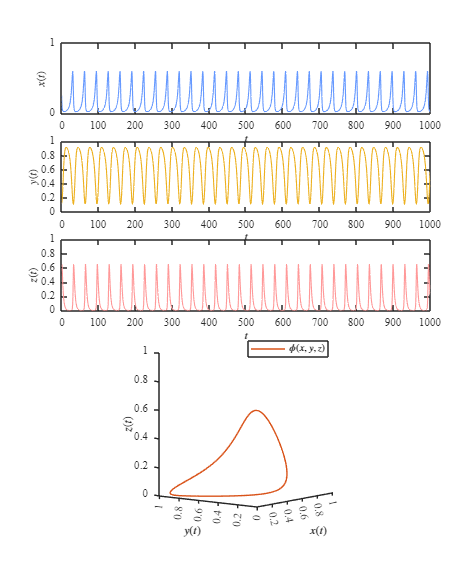

P = [1, 1, 2.5, 0.6, 1, 1.5, 3, 0.3, 0.4];
[t,x,y,z] = system(0.254781,0.115167,0.600527,P,0.9,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'Órbita Periódica.pdf','ContentType','vector')

### 2.3 Intern Cycle Limit

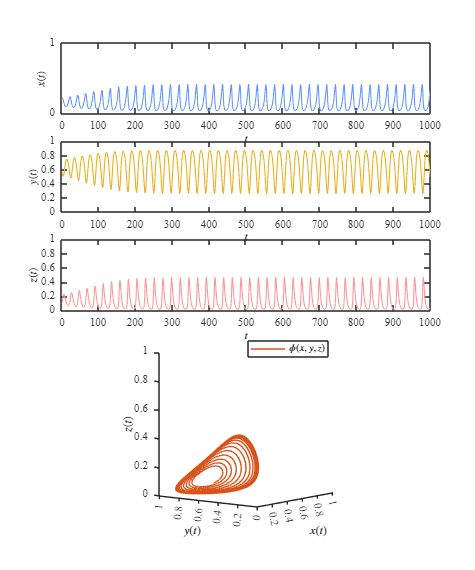

P = [1, 1, 2.5, 0.6, 1, 1.5, 3, 0.3, 0.4];
[t,x,y,z] = system(0.2,0.6,0.1,P,0.8,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'Ciclo Límite Interno.pdf','ContentType','vector')

### 2.4 Extern Cycle Limit  

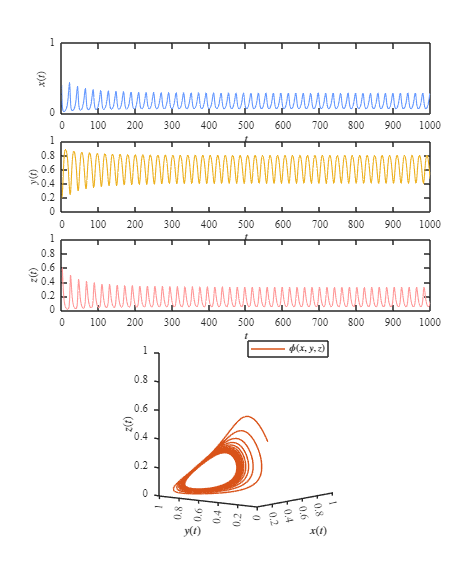

P = [1, 1, 2.5, 0.6, 1, 1.5, 3, 0.3, 0.4];
[t,x,y,z] = system(0.4,0.2,0.4,P,0.75,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'Ciclo Límite Externo.pdf','ContentType','vector')

### 2.5 Equilibrium Points 

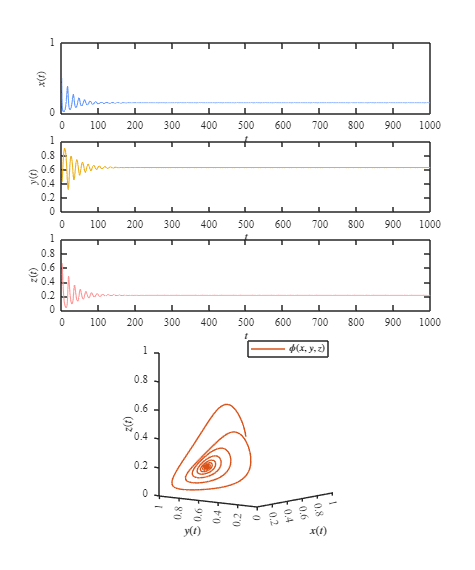

P = [1, 1, 2.5, 0.6, 1, 1.5, 3, 0.3, 0.4];
[t,x,y,z] = system(0.5,0.5,0.4,P,0.5,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'Convergencia hacia un punto de equilibrio.pdf','ContentType','vector')

## 3. Not Normalized Mathematical Models 

### 3.1 Chaotic Atractor [not normalized]

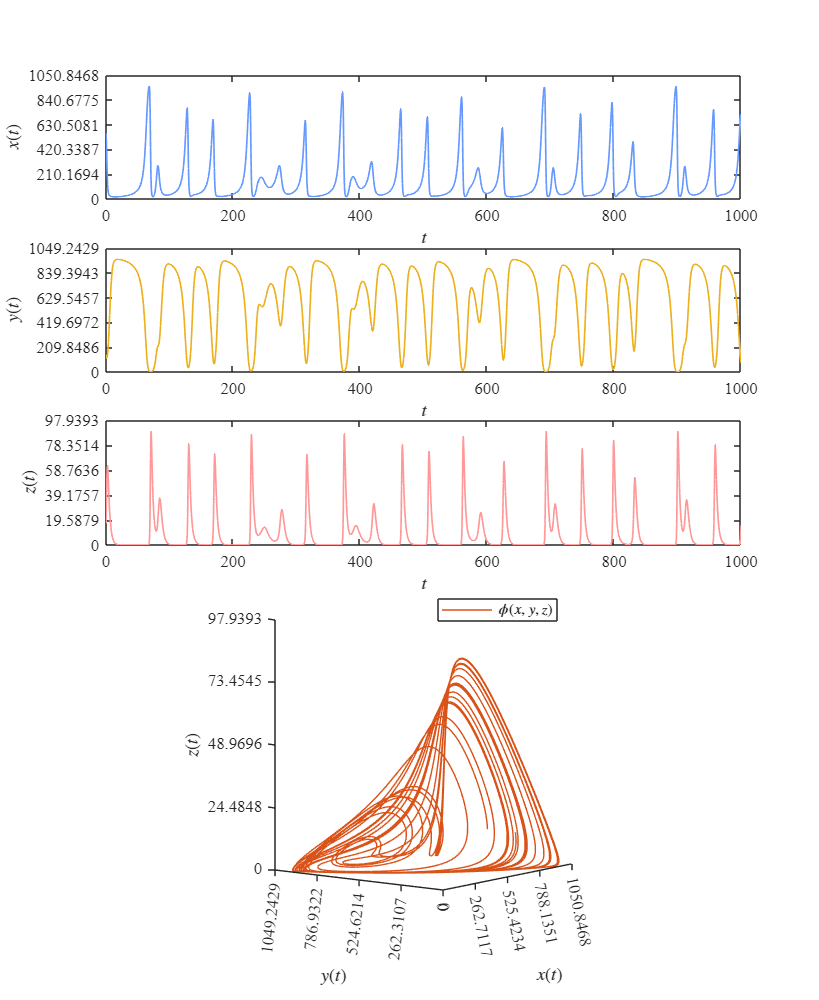

xmax = 1E3; ymax = 1E3; zmax = 1E2; 
b1 = 1/xmax; a12 = 1/ymax; a13 = 2.5/zmax; 
b2 = 1/ymax; a21 = 1.5/xmax; 
r3 = 3/xmax; a31 = 0.3/xmax; 
r1 = 1; r2 = 0.6; d3 = 0.4; 
P = [r1 b1 a13 r2 b2 a21 r3 a31 d3];

rhoi = 0;
dt = 1E-2;
x0 = 0.555*xmax; 
y0 = 0.148*ymax; 
z0 = 0.172*zmax; 
tend = 1000;

[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotcancers(t,x,y,z); exportgraphics(gcf,'Atractor caotico no-normalizado.pdf','ContentType','vector')

### 3.2 Internal Limit Cycle [not normalized]

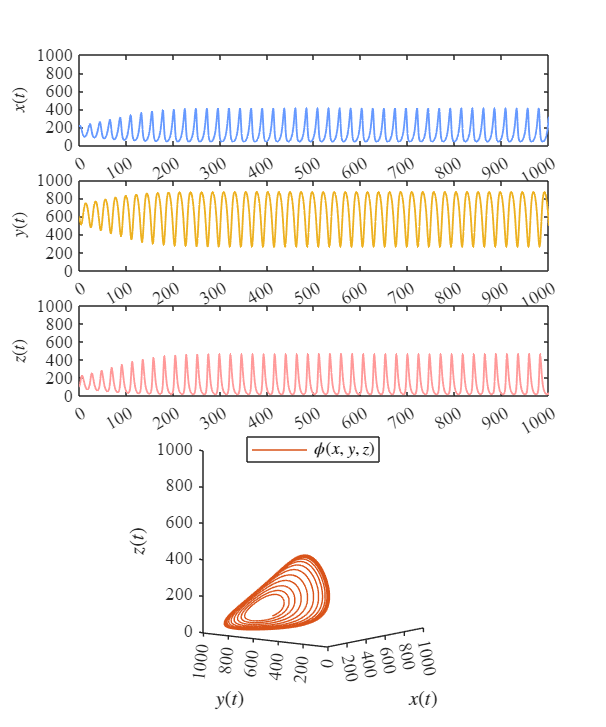

xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
P = [r1, b1, a13, r2, b2, a21, r3, a31, d3];
rhoi = 0;
x0 = 0.2*xmax; y0 = 0.6*ymax; z0 = 0.1*zmax;
dt = 1E-2; tend = 1000;
[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOsNN(t,x,y,z)
exportgraphics(gcf,'Ciclo Límite Interno No Normalizado.pdf','ContentType','vector')

### **4. Equilibrium points and Jacobian Matrix**

clc; clear; close all; warning('off','all')

% Definir variables simbólicas
syms x y z r1 b1 a13 r2 b2 a21 r3 a31 d3 a12 rhoi

% Ecuaciones del sistema
dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
dy = r2*y*(1 - b2*y) - a21*x*y;
dz = (r3 - a31)*x*z - d3*z + rhoi;

% Matriz Jacobiana del sistema
J = jacobian([dx, dy, dz], [x, y, z]);
fprintf('Jacobian matrix of the Lotka-Volterra system:\n'); disp(J)

Jacobian matrix of the Lotka-Volterra system:


$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x & -a_{12}\,x & -a_{13}\,x\\ -a_{21}\,y & -a_{21}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y & 0\\ -z\,\left(a_{31}-r_{3}\right) & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right) \end{array}\right)$$

dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z ==0;
dy = r2*y*(1 - b2*y) - a21*x*y ==0;
dz = (r3 - a31)*x*z - d3*z + rhoi ==0;
equilibria = solve([dx, dy, dz], [x, y, z]);

for i = 1:6
    xe(i,1) = simplify(equilibria.x(i));
    ye(i,1) = simplify(equilibria.y(i));
    ze(i,1) = simplify(equilibria.z(i));

   disp(['Equilibrium points of the system: ', num2str(i)])
    disp(['x', num2str(i), ' = ', char(xe(i,1))]);
    disp(['y', num2str(i), ' = ', char(ye(i,1))]);
    disp(['z', num2str(i), ' = ', char(ze(i,1))]);

end

Equilibrium points of the system: 1


x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3))


y1 = 0


z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 2


x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 3


x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 4


x4 = 0


y4 = 1/b2


z4 = rhoi/d3


Equilibrium points of the system: 5


x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3))


y5 = 0


z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 6


x6 = 0


y6 = 0


z6 = rhoi/d3


### 4.1 Equilibrium points with no treatment 

clear
a12i = [1;0.9;0.8;0.75;0.5];

a12i =     1.0000
    0.9000
    0.8000
    0.7500
    0.5000


r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 0;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    xe = [x1; x2; x3; x4; x5; x6]; ye = [y1; y2; y3; y4; y5; y6]; ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 1


Treatment rhoi = 0


        x*           y*           z*     
    ___________    _______    ___________

        0.14815          0        0.34074
        0.14815    0.62963       0.088889
    -4.5688e-17          1    -5.4826e-17
              0          1              0
              1          0     2.4672e-17
              0          0              0



Equilibrium points with a12 = 0.9


Treatment rhoi = 0


      x*         y*           z*     
    _______    _______    ___________

    0.14815          0        0.34074
    0.14815    0.62963        0.11407
      -0.08        1.2    -5.4826e-17
          0          1              0
          1          0     2.4672e-17
          0          0              0



Equilibrium points with a12 = 0.8


Treatment rhoi = 0


      x*         y*           z*     
    _______    _______    ___________

    0.14815          0        0.34074
    0.14815    0.62963        0.13926
       -0.2        1.5    -1.3706e-16
          0          1              0
          1          0     2.4672e-17
          0          0              0



Equilibrium points with a12 = 0.75


Treatment rhoi = 0


       x*         y*           z*    
    ________    _______    __________

     0.14815          0       0.34074
     0.14815    0.62963       0.15185
    -0.28571     1.7143    1.3706e-16
           0          1             0
           1          0    2.4672e-17
           0          0             0



Equilibrium points with a12 = 0.5


Treatment rhoi = 0


      x*         y*           z*    
    _______    _______    __________

    0.14815          0       0.34074
    0.14815    0.62963       0.21481
         -2          6             0
          0          1             0
          1          0    2.4672e-17
          0          0             0



%para el proyecto no es necesario un for, solo un valor seleccionado para comprobar los puntos de equilibrio.

### 4.2 Equilibrium points with treatment

clear
a12i = [1;0.9;0.8;0.75;0.5]
r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi =1.1*d3*r1/a13;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    xe = [x1; x2; x3; x4; x5; x6]; ye = [y1; y2; y3; y4; y5; y6]; ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 1


Treatment rhoi = 0.176


            x*                   y*                   z*        
    __________________    ________________    __________________

    -0.012761+0i                0+0i             0.4051+0i      
     0.074074+0.32118i    0.81481-0.80294i     0.044444+0.19271i
     0.074074-0.32118i    0.81481+0.80294i     0.044444-0.19271i
            0+0i                1+0i               0.44+0i      
       1.1609+0i                0+0i          -0.064364+0i      
            0+0i                0+0i               0.44+0i      



Equilibrium points with a12 = 0.9


Treatment rhoi = 0.176


            x*                   y*                   z*        
    __________________    ________________    __________________

    -0.012761+0i                0+0i             0.4051+0i      
     0.034074+0.34257i    0.91481-0.85644i     0.057037+0.17129i
     0.034074-0.34257i    0.91481+0.85644i     0.057037-0.17129i
            0+0i                1+0i               0.44+0i      
       1.1609+0i                0+0i          -0.064364+0i      
            0+0i                0+0i               0.44+0i      



Equilibrium points with a12 = 0.8


Treatment rhoi = 0.176


            x*                  y*                   z*        
    __________________    _______________    __________________

    -0.012761+0i               0+0i             0.4051+0i      
    -0.025926+0.36423i    1.0648-0.91057i      0.06963+0.14569i
    -0.025926-0.36423i    1.0648+0.91057i      0.06963-0.14569i
            0+0i               1+0i               0.44+0i      
       1.1609+0i               0+0i          -0.064364+0i      
            0+0i               0+0i               0.44+0i      



Equilibrium points with a12 = 0.75


Treatment rhoi = 0.176


            x*                  y*                  z*        
    __________________    ______________    __________________

    -0.012761+0i              0+0i             0.4051+0i      
    -0.068783+0.37307i    1.172-0.93269i     0.075926+0.13058i
    -0.068783-0.37307i    1.172+0.93269i     0.075926-0.13058i
            0+0i              1+0i               0.44+0i      
       1.1609+0i              0+0i          -0.064364+0i      
            0+0i              0+0i               0.44+0i      



Equilibrium points with a12 = 0.5


Treatment rhoi = 0.176


       x*          y*         z*    
    _________    ______    _________

    -0.012761         0       0.4051
     -0.21756    1.5439      0.17824
      -1.6343    5.0857     0.036571
            0         1         0.44
       1.1609         0    -0.064364
            0         0         0.44



## 5. Chaotic Atractor with treatment [not normalized]

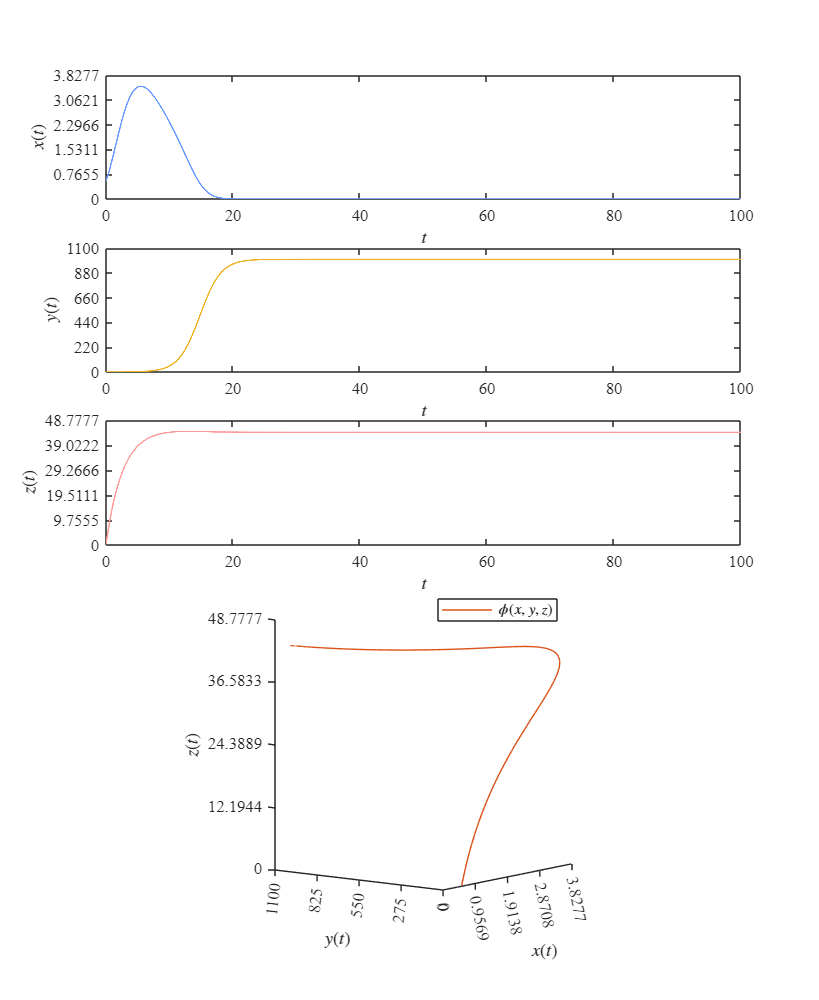

xmax = 1E3; ymax = 1E3; zmax = 1E2; 
b1 = 1/xmax; a12 = 1/ymax; a13 = 2.5/zmax; 
b2 = 1/ymax; a21 = 1.5/xmax; 
r3 = 3/xmax; a31 = 0.3/xmax; 

r1 = 1; r2 = 0.6; d3 = 0.4; 
P = [r1 b1 a13 r2 b2 a21 r3 a31 d3];
rhoi = 1.1*d3*r1/a13; %cambio de rhoi

dt = 1E-2;
x0 = 0.555; 
y0 = 0.148; 
z0 = 0.172;
tend = 100;

[t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotcancers(t,x,y,z); exportgraphics(gcf,'Atractor caotico normalizado rhoi.pdf','ContentType','vector')

### 5.1 Equilibrium points with no treatment for Chaotic Atractor [not normalized]

clear
a12i = 0.8;
xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;

rho1 = 0;

for i = 1:numel(a12i)
    a12 = a12(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

    xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rho1), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 0.0008


Treatment rhoi = 0


      x*        y*          z*    
    ______    ______    __________

    148.15         0        340.74
    148.15    629.63        139.26
      -200      1500    3.2679e-14
         0      1000             0
      1000         0    1.2047e-14
         0         0             0



### 5.2 Equilibrium points with treatment for Chaotic Atractor [not normalized]

clear
a12i = 0.8;
xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;

rho1 = 1.1*d3*r1/a13; %cambio de rhoi

for i = 1:numel(a12i)
    a12 = a12(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rho1 + 4*a12*a13*a21*a31*b2*r2*rho1 - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rho1 + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rho1)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rho1/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rho1 - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rho1 + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rho1/d3;

    xe = [x1; x2; x3; x4; x5; x6]; 
    ye = [y1; y2; y3; y4; y5; y6]; 
    ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rho1), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 0.0008


Treatment rhoi = 176


          x*                 y*                z*       
    _______________    ______________    _______________

    -12.761+0i              0+0i           405.1+0i     
    -25.926+364.23i    1064.8-910.57i      69.63+145.69i
    -25.926-364.23i    1064.8+910.57i      69.63-145.69i
          0+0i           1000+0i             440+0i     
     1160.9+0i              0+0i         -64.364+0i     
          0+0i              0+0i             440+0i     



### 5.2 Local Stability with treatment for Chaotic Atractor [not normalized]

clear
a12i = 0.8;
xmax = 1E3; ymax = 1E3; zmax = 1E3;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;

rhoi = 1.1*(d3*r1)/a13;

for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

     x = [x1; x2; x3; x4; x5; x6]; y = [y1; y2; y3; y4; y5; y6]; z = [z1; z2; z3; z4; z5; z6];
fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)
end

Equilibrium points with a12 = 0.8


Treatment rhoi = 176


       x         y            z         Lambda1    Lambda2     Lambda3 
    _______    ______    ___________    _______    ________    ________

    -12.761         0          405.1    0.18676    -0.18778     0.61914
     399.38    1.5616        -259.47     -1.348      1.1759     0.20312
     148.47    628.82    -2.0088e+05     17.614     -17.794    -0.18506
          0      1000            440          0        -0.6      -800.1
     1160.9         0        -64.364    -1.3543      1.4472     -1.1414
          0         0            440          0        -0.1         0.6



### 5. Conclusión

El sistema biológico tricompartimental analizado exhibe una dinámica altamente sensible al parámetro de bifurcación $a_{12}$, el cual regula la interacción entre las células patológicas y las células sanas. A través de simulaciones numéricas, se observaron comportamientos cualitativamente distintos: desde atractores caóticos hasta órbitas periódicas, ciclos límite internos y externos, así como la convergencia a un punto de equilibrio estable.

Estos resultados muestran cómo pequeñas variaciones en las condiciones de competencia celular pueden alterar significativamente el desarrollo del sistema, lo que es coherente con escenarios reales donde el equilibrio entre proliferación celular y respuesta inmunitaria determina la progresión o control de patologías.

### 6. Functions 

#### 6.1 System Regression 

function [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend)
    r1 = P(1); b1 = P(2); a13 = P(3);
    r2 = P(4); b2 = P(5); a21 = P(6);
    r3 = P(7); a31 = P(8); d3 = P(9);
        t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(n+1,1); x(1) = x0;
    y = zeros(n+1,1); y(1) = y0;
    z = zeros(n+1,1); z(1) = z0;

    for i = 1:n
        [fx,fy,fz] = f(x(i),y(i),z(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        zn = z(i) + fz*dt;

        [fxn,fyn,fzn] = f(xn,yn,zn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
        z(i+1) = z(i) + (fz + fzn)*dt/2;
    end

    function [dx,dy,dz] = f(x,y,z)
        dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
        dy = r2*y*(1 - b2*y) - a21*x*y;
        dz = (r3 - a31)*x*z - d3*z + rhoi;
    end
end

#### **6.2 Functions on an adjusted scale [Normalized]**

function plotEDOs(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,15,18])
     colores = [0.4, 0.6, 1;            % Azul suave
                0.9290 0.6940 0.1250;   % Amarillo suave
                1, 0.6, 0.6;            % Rojo suave
                0.8500 0.3250 0.0980];  % Naranja suave

    subplot(5, 4, 1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color', colores(1,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:1:1)

    subplot(5,4,5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1, 'Color', colores(2,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(5, 4, 9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color', colores(3,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(5, 4, [14, 15, 18, 19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box off; grid off;
    plot3(x, y, z, '-', 'LineWidth', 0.5,'Color', colores(4,:))
    set(gca, 'XDir', 'reverse');
    set(gca, 'YDir', 'reverse');
    xlabel('$x(t)$', 'Interpreter', 'Latex');
    ylabel('$y(t)$', 'Interpreter', 'Latex');
    zlabel('$z(t)$', 'Interpreter', 'Latex');

    view(127.5, 7.5);
    xlim([0 1]); ylim([0 1]); zlim([0 1]);
    xticks(0.2:0.2:1); yticks(0:0.2:1); zticks(0:0.2:1);

    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','Location','Best','Box','On')
end

#### 6.3 Functions on a real scale [Not Normalized]

####     6.3.1 Chaotic Atractor 

function plotcancers(t,x,y,z)
    % Ajuste dinámico de escalas basadas en los datos simulados
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,18,22])
    
    % Colores para líneas
    colores = [0.4, 0.6, 1;            % Azul suave
               0.9290, 0.6940, 0.1250;   % Amarillo suave
               1, 0.6, 0.6;              % Rojo suave
               0.8500, 0.3250, 0.0980];   % Naranja suave

    % Calcular rangos máximos de los datos
    xmaxData = max(x);
    ymaxData = max(y);
    zmaxData = max(z);
    % Añadir un 10% de margen para mejor visualización
    marginFactor = 1.1;
    xlimMax = xmaxData * marginFactor;
    ylimMax = ymaxData * marginFactor;
    zlimMax = zmaxData * marginFactor;

    % Primera subgráfica: x versus t
    subplot(5,4,[1 4]);
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, x, '-', 'LineWidth', 1, 'Color', colores(1,:));
    xlabel('$t$','Interpreter','Latex');
    ylabel('$x(t)$','Interpreter','Latex');
    xlim([0, t(end)]);
    ylim([0, xlimMax]);
    xticks(linspace(0, t(end), 6));
    yticks(linspace(0, xlimMax, 6));

    % Segunda subgráfica: y versus t
    subplot(5,4,5:8);
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, y, '-', 'LineWidth', 1, 'Color', colores(2,:));
    xlabel('$t$','Interpreter','Latex');
    ylabel('$y(t)$','Interpreter','Latex');
    xlim([0, t(end)]);
    ylim([0, ylimMax]);
    xticks(linspace(0, t(end), 6));
    yticks(linspace(0, ylimMax, 6));

    % Tercera subgráfica: z versus t
    subplot(5,4,9:12);
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, z, '-', 'LineWidth', 1, 'Color', colores(3,:));
    xlabel('$t$','Interpreter','Latex');
    ylabel('$z(t)$','Interpreter','Latex');
    xlim([0, t(end)]);
    ylim([0, zlimMax]);
    xticks(linspace(0, t(end), 6));
    yticks(linspace(0, zlimMax, 6));

    % Gráfica 3D: atractor
    subplot(5,4,[14,15,18,19]);
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box off; grid off;
    plot3(x, y, z, '-', 'LineWidth', 0.5, 'Color', colores(4,:));
    set(gca, 'XDir', 'reverse');
    set(gca, 'YDir', 'reverse');
    xlabel('$x(t)$','Interpreter','Latex');
    ylabel('$y(t)$','Interpreter','Latex');
    zlabel('$z(t)$','Interpreter','Latex');
    view(127.5, 7.5);
    xlim([0, xlimMax]);
    ylim([0, ylimMax]);
    zlim([0, zlimMax]);
    xticks(linspace(0, xlimMax, 5));
    yticks(linspace(0, ylimMax, 5));
    zticks(linspace(0, zlimMax, 5));

    % Leyenda
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','Location','Best','Box','On');
end

####     6.3.2 Limit Cycle 

function plotEDOsNN(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,15,18])
    % Colores para líneas
    colores = [0.4, 0.6, 1;            % Azul suave
               0.9290, 0.6940, 0.1250;   % Amarillo suave
               1, 0.6, 0.6;              % Rojo suave
               0.8500, 0.3250, 0.0980];   % Naranja suave

    subplot(5, 4, 1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color', colores(1,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1E3]); yticks(0:0.2E3:1E3)

    subplot(5, 4, 5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1, 'Color', colores(2,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1E3]); yticks(0:0.2E3:1E3)

    subplot(5, 4, 9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color', colores(3,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1E3]); yticks(0:0.2E3:1E3)

    subplot(5, 4, [14, 15, 18, 19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box off; grid off;
    plot3(x, y, z, '-', 'LineWidth', 0.5,'Color', colores(4,:))
    set(gca, 'XDir', 'reverse');
    set(gca, 'YDir', 'reverse');
    xlabel('$x(t)$', 'Interpreter', 'Latex');
    ylabel('$y(t)$', 'Interpreter', 'Latex');
    zlabel('$z(t)$', 'Interpreter', 'Latex');
    view(127.5, 7.5);
    xlim([0 1E3]); ylim([0 1E3]); zlim([0 1E3]);
    xticks(0.2E3:0.2E3:1E3); yticks(0:0.2E3:1E3); zticks(0:0.2E3:1E3);
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','Location','Best','Box','On')
end

## 7. References  

[1]  Paul. A. Valle, Syllabus de Biomatemáticas para la asignatura de Gemelos Digitales, Tecnológico Nacional de México/IT Tijuana, Tijuana, B.C., México, 2025. Permalink: https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf

[2] Dominik Wordaz & Natalia L. Komarova, Dynamics of Cancer: Mathematical Foundations of Oncology, University of California, Irvine, USA, 2014.

[3] Robert A. Gatenby & Thomas L. Vincent, "Application of quantitative models from population biology and evolutionary game theory to tumor therapeutic strategies," Molecular Cancer Therapeutics, vol. 2, no. 9, pp. 919–927, Jun 2003.